# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


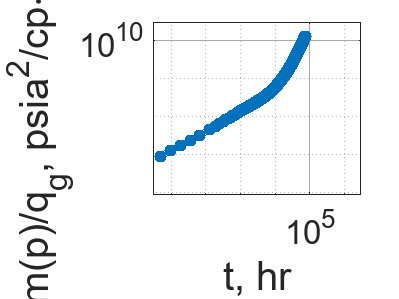


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 195

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_195 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\50%\noisy_data_5.txt", opts)

noisy_RNP_195 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    9.4746e+07
    0.33041    1.9565e+06
     0.4862    2.5398e+08
    0.79777    3.4782e+06
     1.4209    1.3911e+08
     2.6672    5.1713e+07
     5.0773    8.8236e+06
     9.8974    6.2288e+07
     19.198    1.9539e+08
     35.645    2.6951e+08
      66.06    3.1893e+07
     124.99    2.4808e+08
     188.99    8.5548e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99    2.0936e+08


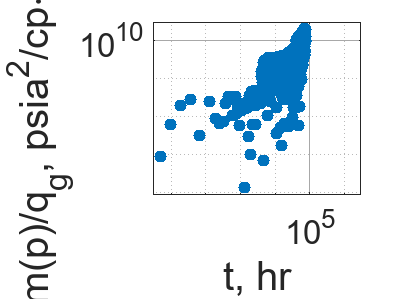


% Plot
loglog(noisy_RNP_195.t, noisy_RNP_195.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 195", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 195

logRNP_195 = log(noisy_RNP_195.RNP);

#### Window: 3

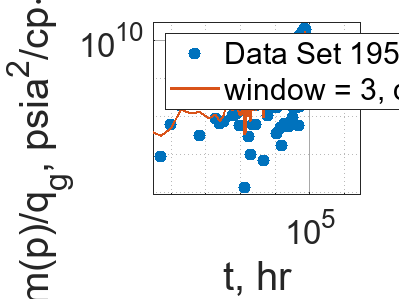

% Plot
loglog(noisy_RNP_195.t, noisy_RNP_195.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 195");
% title("Noisy RNP Data Set 195", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_195_31 = smooth(logRNP_195, 3, "sgolay", 1);
smoothedRNP_195_31 = exp(smoothedLogRNP_195_31);
residual_195_31 = (true_RNP.RNP - smoothedRNP_195_31) ./ (0.3413 .* true_RNP.RNP);
sse_195_31 = sum(residual_195_31 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

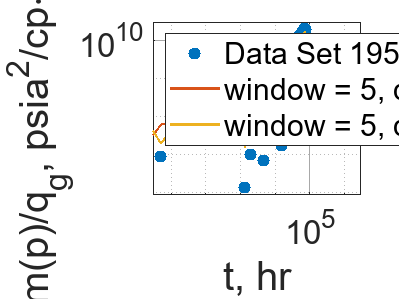

% Plot
loglog(noisy_RNP_195.t, noisy_RNP_195.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 195");
% title("Noisy RNP Data Set 195", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_195_51 = smooth(logRNP_195, 5, "sgolay", 1);
smoothedRNP_195_51 = exp(smoothedLogRNP_195_51);
residual_195_51 = (true_RNP.RNP - smoothedRNP_195_51) ./ (0.3413 .* true_RNP.RNP);
sse_195_51 = sum(residual_195_51 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_195_52 = smooth(logRNP_195, 5, "sgolay", 2);
smoothedRNP_195_52 = exp(smoothedLogRNP_195_52);
residual_195_52 = (true_RNP.RNP - smoothedRNP_195_52) ./ (0.3413 .* true_RNP.RNP);
sse_195_52 = sum(residual_195_52 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

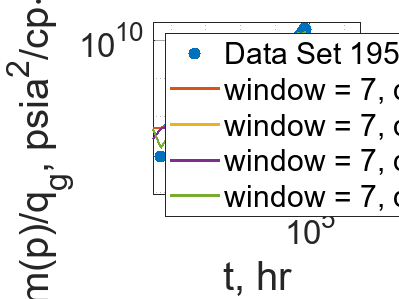

% Plot
loglog(noisy_RNP_195.t, noisy_RNP_195.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 195");
% title("Noisy RNP Data Set 195", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_195_71 = smooth(logRNP_195, 7, "sgolay", 1);
smoothedRNP_195_71 = exp(smoothedLogRNP_195_71);
residual_195_71 = (true_RNP.RNP - smoothedRNP_195_71) ./ (0.3413 .* true_RNP.RNP);
sse_195_71 = sum(residual_195_71 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_195_72 = smooth(logRNP_195, 7, "sgolay", 2);
smoothedRNP_195_72 = exp(smoothedLogRNP_195_72);
residual_195_72 = (true_RNP.RNP - smoothedRNP_195_72) ./ (0.3413 .* true_RNP.RNP);
sse_195_72 = sum(residual_195_72 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_195_73 = smooth(logRNP_195, 7, "sgolay", 3);
smoothedRNP_195_73 = exp(smoothedLogRNP_195_73);
residual_195_73 = (true_RNP.RNP - smoothedRNP_195_73) ./ (0.3413 .* true_RNP.RNP);
sse_195_73 = sum(residual_195_73 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_195_74 = smooth(logRNP_195, 7, "sgolay", 4);
smoothedRNP_195_74 = exp(smoothedLogRNP_195_74);
residual_195_74 = (true_RNP.RNP - smoothedRNP_195_74) ./ (0.3413 .* true_RNP.RNP);
sse_195_74 = sum(residual_195_74 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

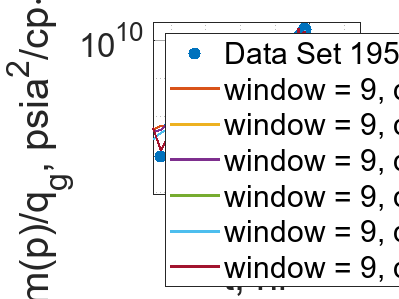

% Plot
loglog(noisy_RNP_195.t, noisy_RNP_195.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 195");
% title("Noisy RNP Data Set 195", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_195_91 = smooth(logRNP_195, 9, "sgolay", 1);
smoothedRNP_195_91 = exp(smoothedLogRNP_195_91);
residual_195_91 = (true_RNP.RNP - smoothedRNP_195_91) ./ (0.3413 .* true_RNP.RNP);
sse_195_91 = sum(residual_195_91 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_195_92 = smooth(logRNP_195, 9, "sgolay", 2);
smoothedRNP_195_92 = exp(smoothedLogRNP_195_92);
residual_195_92 = (true_RNP.RNP - smoothedRNP_195_92) ./ (0.3413 .* true_RNP.RNP);
sse_195_92 = sum(residual_195_92 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_195_93 = smooth(logRNP_195, 9, "sgolay", 3);
smoothedRNP_195_93 = exp(smoothedLogRNP_195_93);
residual_195_93 = (true_RNP.RNP - smoothedRNP_195_93) ./ (0.3413 .* true_RNP.RNP);
sse_195_93 = sum(residual_195_93 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_195_94 = smooth(logRNP_195, 9, "sgolay", 4);
smoothedRNP_195_94 = exp(smoothedLogRNP_195_94);
residual_195_94 = (true_RNP.RNP - smoothedRNP_195_94) ./ (0.3413 .* true_RNP.RNP);
sse_195_94 = sum(residual_195_94 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_195_95 = smooth(logRNP_195, 9, "sgolay", 5);
smoothedRNP_195_95 = exp(smoothedLogRNP_195_95);
residual_195_95 = (true_RNP.RNP - smoothedRNP_195_95) ./ (0.3413 .* true_RNP.RNP);
sse_195_95 = sum(residual_195_95 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_195_96 = smooth(logRNP_195, 9, "sgolay", 6);
smoothedRNP_195_96 = exp(smoothedLogRNP_195_96);
residual_195_96 = (true_RNP.RNP - smoothedRNP_195_96) ./ (0.3413 .* true_RNP.RNP);
sse_195_96 = sum(residual_195_96 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

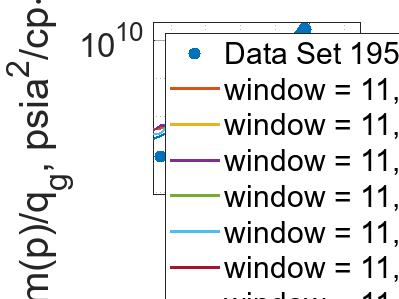

% Plot
loglog(noisy_RNP_195.t, noisy_RNP_195.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 195");
% title("Noisy RNP Data Set 195", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_195_111 = smooth(logRNP_195, 11, "sgolay", 1);
smoothedRNP_195_111 = exp(smoothedLogRNP_195_111);
residual_195_111 = (true_RNP.RNP - smoothedRNP_195_111) ./ (0.3413 .* true_RNP.RNP);
sse_195_111 = sum(residual_195_111 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_195_112 = smooth(logRNP_195, 11, "sgolay", 2);
smoothedRNP_195_112 = exp(smoothedLogRNP_195_112);
residual_195_112 = (true_RNP.RNP - smoothedRNP_195_112) ./ (0.3413 .* true_RNP.RNP);
sse_195_112 = sum(residual_195_112 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_195_113 = smooth(logRNP_195, 11, "sgolay", 3);
smoothedRNP_195_113 = exp(smoothedLogRNP_195_113);
residual_195_113 = (true_RNP.RNP - smoothedRNP_195_113) ./ (0.3413 .* true_RNP.RNP);
sse_195_113 = sum(residual_195_113 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_195_114 = smooth(logRNP_195, 11, "sgolay", 4);
smoothedRNP_195_114 = exp(smoothedLogRNP_195_114);
residual_195_114 = (true_RNP.RNP - smoothedRNP_195_114) ./ (0.3413 .* true_RNP.RNP);
sse_195_114 = sum(residual_195_114 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_195_115 = smooth(logRNP_195, 11, "sgolay", 5);
smoothedRNP_195_115 = exp(smoothedLogRNP_195_115);
residual_195_115 = (true_RNP.RNP - smoothedRNP_195_115) ./ (0.3413 .* true_RNP.RNP);
sse_195_115 = sum(residual_195_115 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_195_116 = smooth(logRNP_195, 11, "sgolay", 6);
smoothedRNP_195_116 = exp(smoothedLogRNP_195_116);
residual_195_116 = (true_RNP.RNP - smoothedRNP_195_116) ./ (0.3413 .* true_RNP.RNP);
sse_195_116 = sum(residual_195_116 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_195_117 = smooth(logRNP_195, 11, "sgolay", 7);
smoothedRNP_195_117 = exp(smoothedLogRNP_195_117);
residual_195_117 = (true_RNP.RNP - smoothedRNP_195_117) ./ (0.3413 .* true_RNP.RNP);
sse_195_117 = sum(residual_195_117 .^ 2);
loglog(noisy_RNP_195.t, smoothedRNP_195_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;